origin = [0,0]

origin =      0     0


max_traction = 0.75

max_traction = 0.7500

Gc = 0.375

Gc = 0.3750

Kn = 2.5

Kn = 2.5000

damage_sep = max_traction / Kn

damage_sep = 0.3000

max_sep = ((Gc - (max_traction * damage_sep / 2)) / max_traction * 2) + damage_sep

max_sep = 1

apex = [damage_sep, max_traction]

apex =     0.3000    0.7500


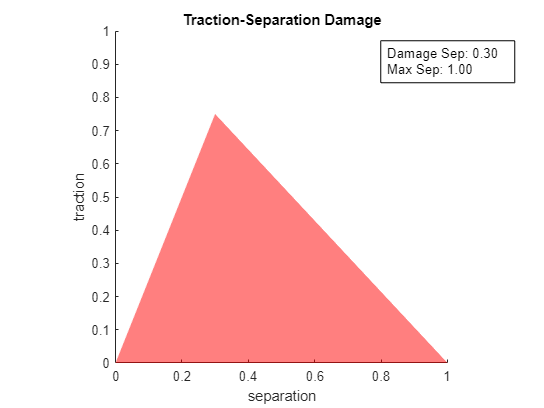


% Define vertices of the triangle
v = [origin; max_sep,0; damage_sep, max_traction]; % Vertices of equilateral triangle

% Define faces of the triangle
f = [1, 2, 3]; % Single face

% Plot the triangle
figure;
patch('Faces', f, 'Vertices', v, 'FaceColor', 'red', 'FaceAlpha', 0.5, 'EdgeColor', 'none');
hold on;

% Plot the random points within the triangle
%scatter(points(:,1), points(:,2), 10, 'r', 'filled');
xlabel('separation');
ylabel('traction');
title('Traction-Separation Damage');

% Set axis limits
axis equal;
xlim([0, 1]);
ylim([0, 1]);

textString = sprintf('Damage Sep: %.2f\nMax Sep: %.2f', damage_sep, max_sep);
annotation('textbox', [0.7, 0.7, 0.2, 0.2], 'String', textString, 'FitBoxToText', 'on');